# Opgave1 - M3NUM1 E15 Ordinær eksamen

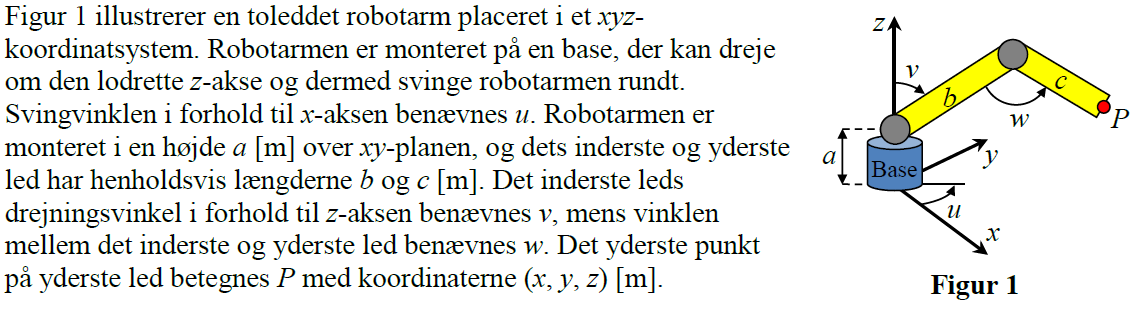

## a)

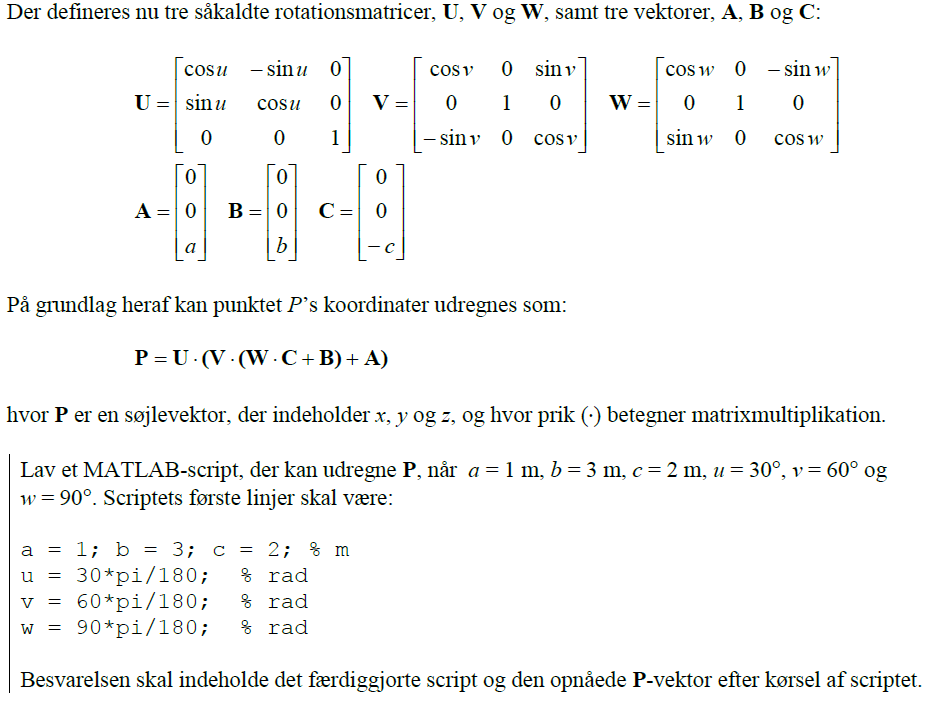

a = 1; b = 3; c = 2; % m
u = 30*pi/180; % rad
v = 60*pi/180; % rad
w = 90*pi/180; % rad

%Vi opskriver matricerne
U = [cos(u) -sin(u) 0
    sin(u) cos(u) 0
    0 0 1];

V = [cos(v) 0 sin(v)
    0 1 0
    -sin(v) 0 cos(v)];

W = [cos(w) 0 -sin(w)
    0 1 0
    sin(w) 0 cos(w)];

%Vi opskriver vektorene
A = [0; 0; a];

B = [0; 0; b];

C = [0; 0; -c];

%Der udregnes hvor resultatet bliver en vektor
P = U * (V * (W * C + B) + A) %obs rækkefølgen matricer ganges sammen med er ikke ligegyldig.

P =     3.1160
    1.7990
    0.7679


## b)

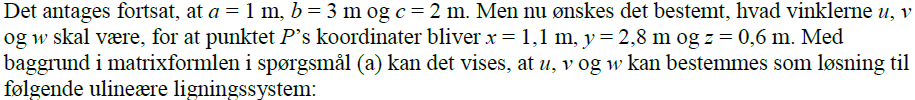

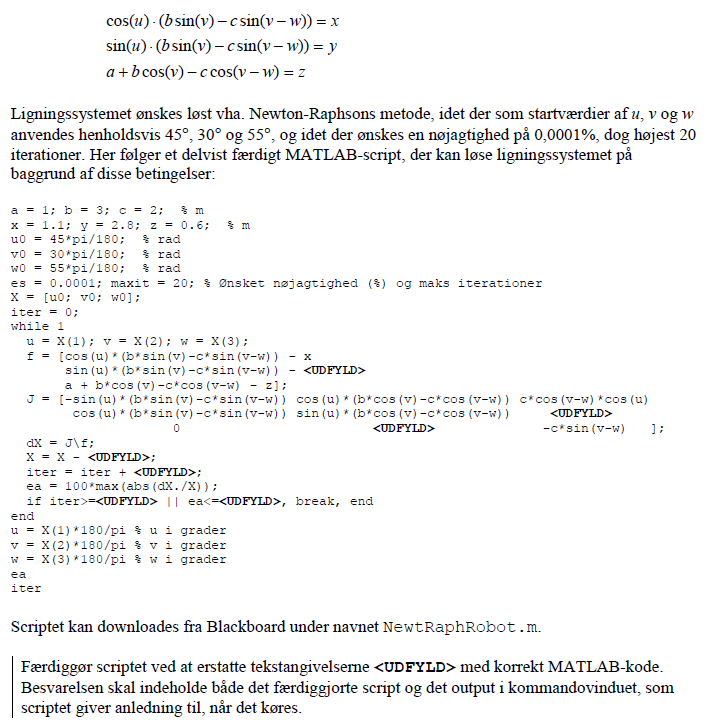

Vi finder først de afledte funktioner af f

syms u v w a b c x y z

f = [cos(u)*(b*sin(v)-c*sin(v-w)) - x %resultatet af hver ligning sættes = 0
     sin(u)*(b*sin(v)-c*sin(v-w)) - y
     a + b*cos(v)-c*cos(v-w) - z];

for i = 1:length(f)
    diff(f(i), u)
    diff(f(i), v)
    diff(f(i), w)
end

$$ans = -\sin\left(u\right)\,\left(b\,\sin\left(v\right)-c\,\sin\left(v-w\right)\right)$$

$$ans = \cos\left(u\right)\,\left(b\,\cos\left(v\right)-c\,\cos\left(v-w\right)\right)$$

$$ans = c\,\cos\left(v-w\right)\,\cos\left(u\right)$$

$$ans = \cos\left(u\right)\,\left(b\,\sin\left(v\right)-c\,\sin\left(v-w\right)\right)$$

$$ans = \sin\left(u\right)\,\left(b\,\cos\left(v\right)-c\,\cos\left(v-w\right)\right)$$

$$ans = c\,\cos\left(v-w\right)\,\sin\left(u\right)$$

$$ans = 0$$

$$ans = c\,\sin\left(v-w\right)-b\,\sin\left(v\right)$$

$$ans = -c\,\sin\left(v-w\right)$$

Her bruges ligning 6 og 8

a = 1; b = 3; c = 2; % m
x = 1.1; y = 2.8; z = 0.6; % m
u0 = 45*pi/180; % rad
v0 = 30*pi/180; % rad
w0 = 55*pi/180; % rad
es = 0.0001; maxit = 20; % Ønsket nøjagtighed (%) og maks iterationer
X = [u0; v0; w0];
iter = 0;
while 1 
    u = X(1); v = X(2); w = X(3);

    %resultatet af hver ligning sættes = 0
    f = [cos(u)*(b*sin(v)-c*sin(v-w)) - x 
        sin(u)*(b*sin(v)-c*sin(v-w)) - y
        a + b*cos(v)-c*cos(v-w) - z];

    % de afledte funktioner indsættes i en matrix
    J = [-sin(u)*(b*sin(v)-c*sin(v-w)) cos(u)*(b*cos(v)-c*cos(v-w)) c*cos(v-w)*cos(u) 
        cos(u)*(b*sin(v)-c*sin(v-w)) sin(u)*(b*cos(v)-c*cos(v-w)) c*cos(v - w)*sin(u)
        0 c*sin(v - w) - b*sin(v) -c*sin(v-w) ];

    dX = J\f; %løser ligningsystemet J*dx = f
    X = X - J\f;
    iter = iter + 1;
    ea = 100*max(abs(dX./X));
    if iter>=maxit || ea<=es, break, end
end
u = X(1)*180/pi % u i grader

u = 68.5523

v = X(2)*180/pi % v i grader

v = 58.8704

w = X(3)*180/pi % w i grader

w = 71.5889

ea

ea = 4.5887e-05

iter

iter = 5

# Opgave 4 - M3NUM1 F16 Ordinær eksamen

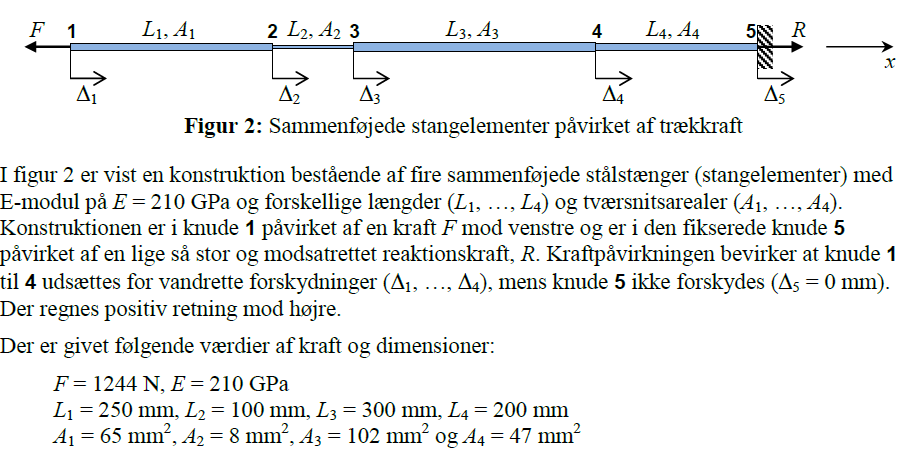

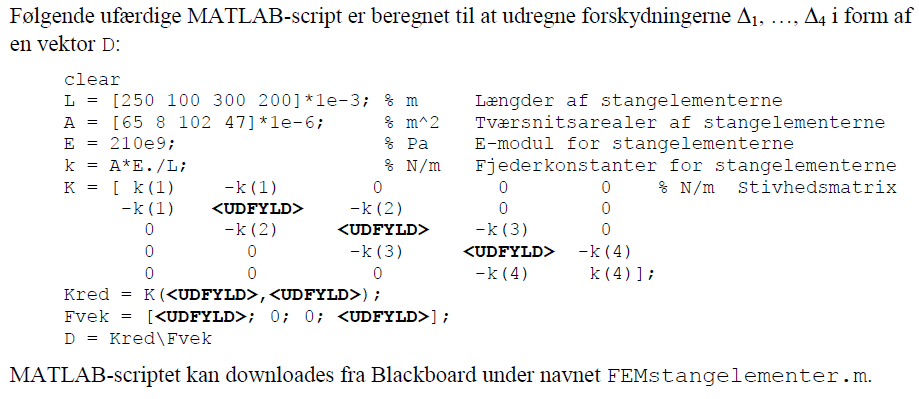

## a)

clear
L = [250 100 300 200]*1e-3; % m Længder af stangelementerne
A = [65 8 102 47]*1e-6; % m^2 Tværsnitsarealer af stangelementerne
E = 210e9; % Pa E-modul for stangelementerne

k = A*E./L; % N/m Fjederkonstanter for stangelementerne

K = [ k(1) -k(1) 0 0 0 % N/m Stivhedsmatrix
    -k(1) k(1)+k(2) -k(2) 0 0
    0 -k(2) k(2)+k(3) -k(3) 0
    0 0 -k(3) k(3)+k(4) -k(4)
    0 0 0 -k(4) k(4)];

Kred = K(1:4,1:4);
F = 1244; %N
Fvek = [F; 0; 0; F];
D = Kred\Fvek;

format("shortG")
tab = table(D, VariableNames={'Forskydning i punkt'}, RowNames={'\Delta_1', '\Delta_2', '\Delta_3', '\Delta_4'})

tab = 4×1 table
                Forskydning i punkt
                ___________________

    \Delta_1        0.00016467     
    \Delta_2        0.00014189     
    \Delta_3        6.7838e-05     
    \Delta_4        5.0415e-05     


## b)

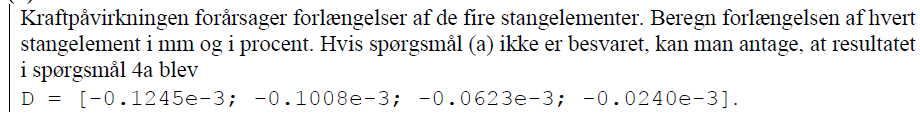

format shortG %laver færrer decimaler

%flipper vectorne så vi starter ved inspændingen
D_lang = flip(D);
L_rev = flip(L);

%sætter start værdi og lister til forloop
d = 0;
forlaengelse = [];
d_proc = [];

%forloop udregner forlængelse
for i = 1:length(L) 
     d = D_lang(i) - d;
     forlaengelse(i) = d * 1000;
     d_proc(i) = d/L_rev(i) * 100;
end

%opsætter tabel
clear table
tab_delta = table(flip(forlaengelse'), flip(d_proc'), VariableNames={'Forlængelse(mm)', 'Forlængelse(%)'})

tab_delta = 4×2 table
    Forlængelse(mm)    Forlængelse(%)
    _______________    ______________

       0.040207           0.016083   
        0.12446            0.12446   
       0.017423          0.0058077   
       0.050415           0.025208   


# Opgave 5 - M3NUM1 E18 Ordinær eksamen

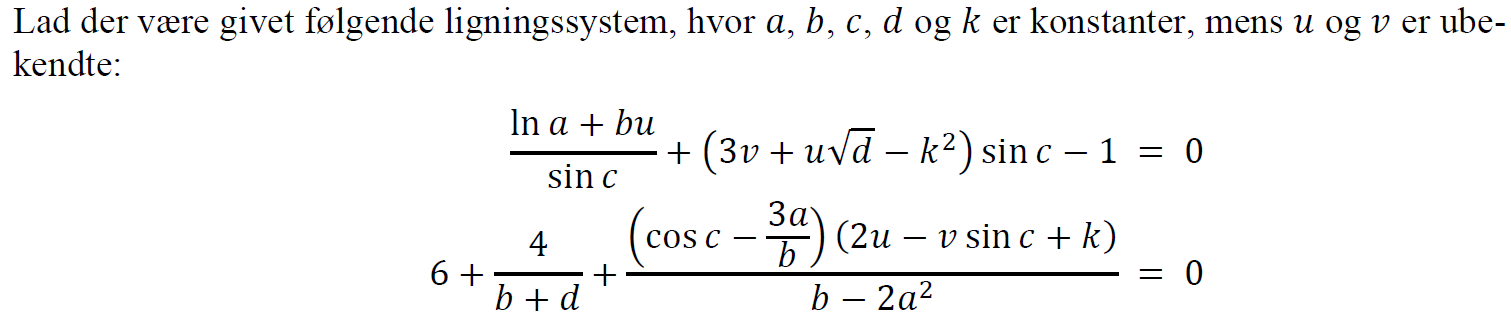

## 5a)

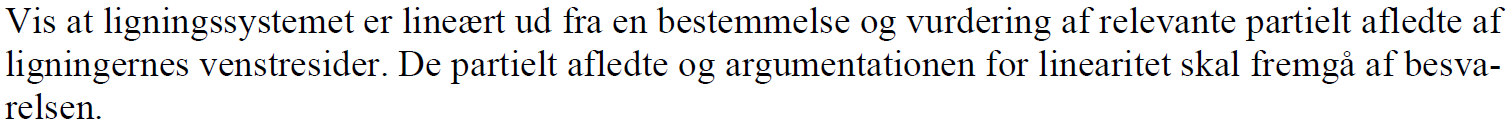

Vi starter med at sætte alle konstanter til 1 og variablerne som symboler der med kan vi hurtigt se om ligningen ser ud til avære være lineær

syms u v
a = 1;
b = 1;
c = 1;
d = 1;
k = 1;
f1 = (log(a)+b*u) / sin(c) + (3*v + u * sqrt(d) - k^2) * sin(c) - 1

$$f1 = \frac{34643844702534016924092238187345\,u}{17067059183461908934129239457792}+\frac{11368945240871781\,v}{4503599627370496}-\frac{8293248040994423}{4503599627370496}$$

Vi ser således at ligningen står på lineær form $a \cdot u + b \cdot v + konstant$

For ekstra analyse kan vi også undersøge ligningen ved at lave partiel differentiering for at få en konstant

vpa(diff(f1, v),3) %ligning 1 differentieres og evalueres med 3 betydende cifre

$$ans = 2.52$$

vpa(diff(f1, u), 3)

$$ans = 2.03$$

Vi ser at vi får en konstant ud ved hver partieldifferentiering og vi har således en linær ligning

Det samme gentages for ligning 2

f2 = 6 + 4/(b+d) + (cos(c)-3*a/b) * (2*u - v*sin(c) + k) / (b-2*a^2) 

$$f2 = \frac{5538746809368157\,u}{1125899906842624}-\frac{20989903059586623388313487092539\,v}{10141204801825835211973625643008}+\frac{23553145318850141}{2251799813685248}$$

vpa(diff(f2, v), 3)

$$ans = -2.07$$

vpa(diff(f2, u), 3)

$$ans = 4.92$$

Ved anden ligning har vi igen kun en konstant tilbage, de to ligninger har altså en konstant hældning.

**Vi har således 2 lineær ligninger med to ubekndte.**

## 5b)

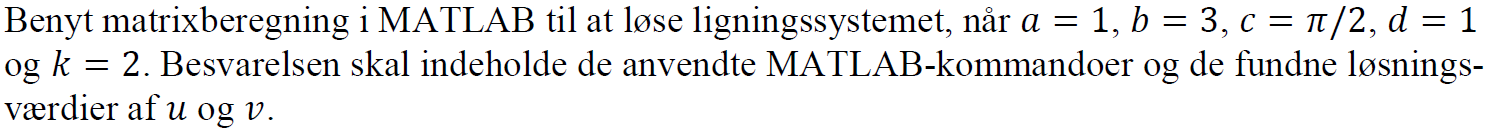

a = 1;
b = 3;
c = pi/2;
d = 1;
k = 2;

%Vi bruger den indbyggede funktion til at omdanne vore lineær ligning til
%en 2x2 matrix vi kan udregne
eqns = [f1 == 0,
        f2 == 0]; %definer ligningerne
[A,B] = equationsToMatrix(eqns); %ligninger omdannes til matrix A med konstanterne B som resultat

X = vpa(linsolve(A,B),5) %Vi kan nu bruge solver funktionen til at løse ligningsystemet

$$X = \left(\begin{array}{c} -1.3594\\ 1.8226 \end{array}\right)$$

%uden den indbyggede funktionen equationsToMatrix(eqns) kan vi også trække
%værdierne ud således

b1 = diff(f1, v)*v + diff(f1, u)*u - f1; %konstanterne udtrækkes
b2 = diff(f2, v)*v + diff(f2, u)*u - f2;

A = [diff(f1, u), diff(f1, v)
    diff(f2, u), diff(f2, v)]; %matrixen opstilles

B = [b1 
    b2]; %konstanterne sættes om løsning til matrixen
X = vpa(linsolve(A,B),5)

$$X = \left(\begin{array}{c} -1.3594\\ 1.8226 \end{array}\right)$$